Matlab has the compiled function pwelch.m, which implements the Welch method. Check the help and try to use it. 					

[**Pxx,f**] = pwelch(X,WINDOW,NOVERLAP,NFFT, FREQRANGE,Fs) `o `Pxx = Power density spectrum 	

`o `F=frequency axis 

`o `X = signal

`o `WINDOW= window type

`o `NOVERLAP = uses NOVERLAP samples of overlap from section to section

`o `FREQRANGE = 'onesided' when X is real and 'twosided' when X is complex.

`o `NFFT = specifies the number of FFT points used to calculate the PSD estimate. `o `Fs = frequency sampling 

INSTRUCTIONS

- **Choose the Window Type and Length**: Use a Hamming window due to its properties that reduce variance. In this example, a window length of 1000 samples is chosen.

- **Set the Overlap Between Windows**: Specify the overlap between consecutive windows to improve the number of windows averaged, which helps reduce variance further. In this example, the overlap is set to one-quarter of the window length, which is 250 samples (1/4 of 1000).

- **Specify the Number of FFT Points**: This should be equal to or greater than the window length. If it is greater, MATLAB will perform zero padding to increase the resolution of the PSD estimate. In this example, it is implied that the number of FFT points is at least 1000, as there is no zero padding mentioned explicitly.

- **Average Over Multiple Segments**: Aiming to average 60 segments for reduced variance, ensure the settings of your `pwelch` function, combined with your data length, allow for this many segments to be averaged. You might need to adjust your data length or windowing scheme accordingly.

%%%

window = hamming(1000); 

noverlap = 250;

nfft = 1000;            

[pxx, f] = pwelch(signal, window, noverlap, nfft, fs);

%%%

**Calculate the power spectrum of x3(k) by implementation of the Welch Method, ****increasing the overlap. What’s happen? **

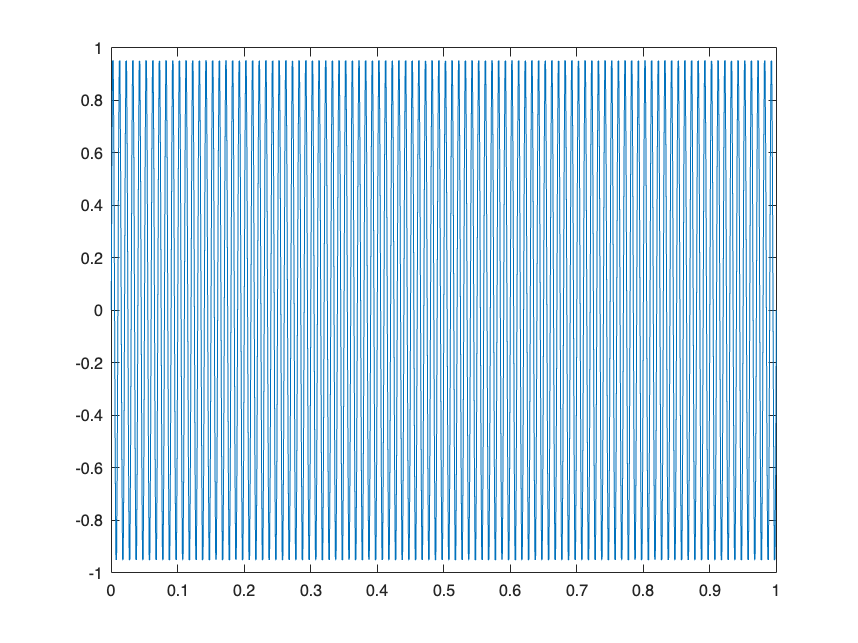

f1 = 100; %Hz
f2 =  120; %Hz
A = 1; % amplitude
t = [0:1/1000:1];
f_s = 1000;
d = 1 - 0; % duration


% f_s = n/(x2-x1) % f_s = n/duration = n/(x2-x1)
% t = [x1:1/f_s:(x2-1)]; 
% so in this case f_s = 1000 -> by reading t definition

% function [x]=generate_sine(frequency,A,fs,duration)
x1 = generate_sine(f1, A, f_s, d);

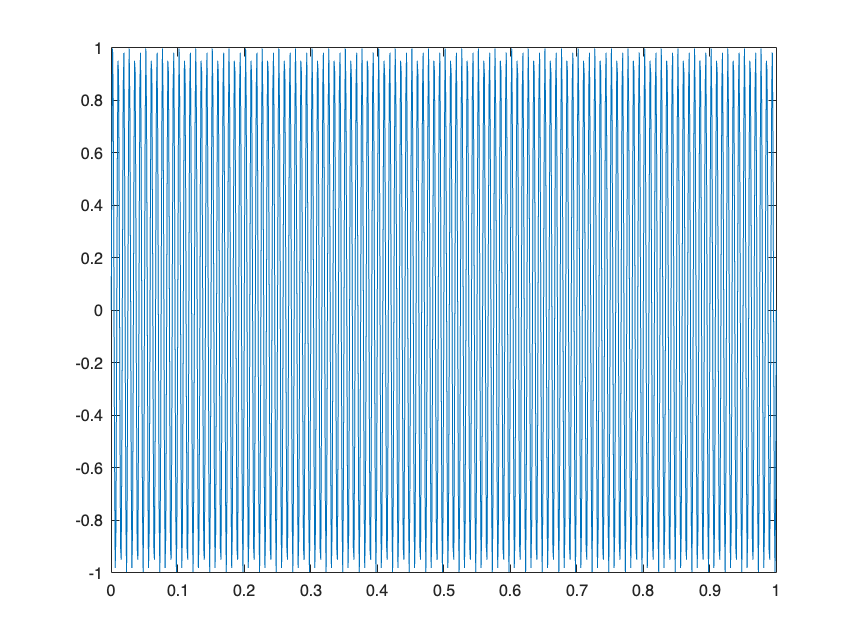

x2 = generate_sine(f2, A, f_s, d);


x3 = x1 + x2;

%function xn=addNoise(x, t, snr)
SNR = 10;
x3_noise = addNoise(x3,t,SNR);

%   pxx = pwelch(x,window,noverlap,nfft)

% Define the Hanning window function
hanning_window = hanning(length(x3_noise));

% Define different NFFT values
NFFT_values = [500, 250, 75];

% Initialize cells to save results
Pxx_results = cell(1, length(NFFT_values));
f_results = cell(1, length(NFFT_values));

% Loop over different NFFT values to calculate and plot the periodogram
for i = 1:length(NFFT_values)
    NFFT = NFFT_values(i); % Ottiene l'i-esimo valore di NFFT
    [Pxx, f] = pwelch(x3_noise, hanning_window, [], NFFT);
    
    % Save the results in cells
    Pxx_results{i} = Pxx;
    f_results{i} = f;

    figure;
    plot(f, 10*log10(Pxx));
    title(['Periodogram with Hanning Window (NFFT = ', num2str(NFFT), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Power/Frequency (dB/Hz)');
    grid on;
end

Calcolo dello spettro attraverso il metodo Welch: 		

Consiste nel suddividere gli N campioni in M segmenti costituiti a loro volta da K campioni e calcolarne successivamente il periodogram. Gli M periodogram sono quindi "averaged" per ridurre la varianza della stima. L'inconveniente principale è che, a differenza del periodogram, perde risoluzione frequenziale poichè andiamo a considerare finestre di campioni più piccole. Tuttavia migliora la bias. La scelta della finestra è cruciale, infatti una finestra rettangolare permette una risoluzione in frequenza migliore e riduce la bias ma aumenta la varianza, invece con una finestra hamming (or hanning) si riduce la varianza ma aumenta la bias e peggiora la risoluzione. 

`% In questo caso si è scelta una finestra hamming per ridurre la varianza e`

`% verificare i risultati per differenti lunghezze della finestra.`			

`% La lunghezza dell'overlap.`					

`% Il numero di "FFT points" che devono essere più grandi della lunghezza`

`% della finestra.`